# Phase Difference Analysis

#### Select subjects


clearvars;
filepath        = 'G:\Shrey\EEGData';
subjects        = CleanDir(filepath);

fakeUI          = figure;
fakeUI.UserData = subjects;
fakeUI.Visible  =  'off';
select_labels(fakeUI,[],subjects);
waitfor(findall(0,'Name','Select Labels'),'BeingDeleted','on');
subjects        = fakeUI.UserData;
close(fakeUI);

layout          = 'C:\Users\User\Documents\GitHub\Deci\Function\Gen_Fun\easycap_rob_eye.mat';


#### Subject-wise WW-test


version = [];
showlaplace     = true;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version]; 
    stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    
    % sort channel labels according to position on the head
    stimlocked  = sortcells(stimlocked);
    d3locked    = sortcells(d3locked);
    
    % Comparing D1 (dhist1(:,:,1,:)) and D3 (dhist2(:,:,1,:))
    for chani = 1:size(stimlocked.dhist,1)
        for chanj = 1:size(stimlocked.dhist,2)
            [wwtest(subs).pval(chani,chanj), wwtest(subs).fstat(chani,chanj), wwtest(subs).table{chani,chanj},wwtest(subs).rw(chani,chanj)] = circ_wwtest((stimlocked.dhist(chani,chanj,1,:)),(d3locked.dhist(chani,chanj,1,:)));
        end
    end 
    
    % Generate plots which show significance
    plottest(subs) = wwtest(subs);
    % Retain only one diagonal matrix
    if size(plottest(subs).pval,1) == size(plottest(subs).pval,2)
        for i = 1:size(plottest(subs).pval,1)
            plottest(subs).pval(i,i:end)    = NaN;
            plottest(subs).fstat(i,i:end)   = NaN;
            plottest(subs).rw(i,i:end)      = NaN;
        end
    end
    
    % Remove elements with unacceptablye high p-values or very low
    plottest(subs).pval((plottest(subs).pval >= (0.05/(58*58))) | (plottest(subs).rw < 0.45)) = NaN; 
    figure('units','normalized','outerposition',[0 0 1 1]);
    imagesc(plottest(subs).pval);
%     imagesc(plottest(subs).pval<(0.05/(58*58)) & plottest(subs).rw>0.45)
    xticks(1:length(stimlocked.cellperms{1}));
    yticks(1:length(stimlocked.cellperms{2}));
    xticklabels(stimlocked.cellperms{1});
    yticklabels(stimlocked.cellperms{1});
    xlabel('Channels');
    ylabel('Channels');
end


#### Validation - Plot histograms of significant pairs

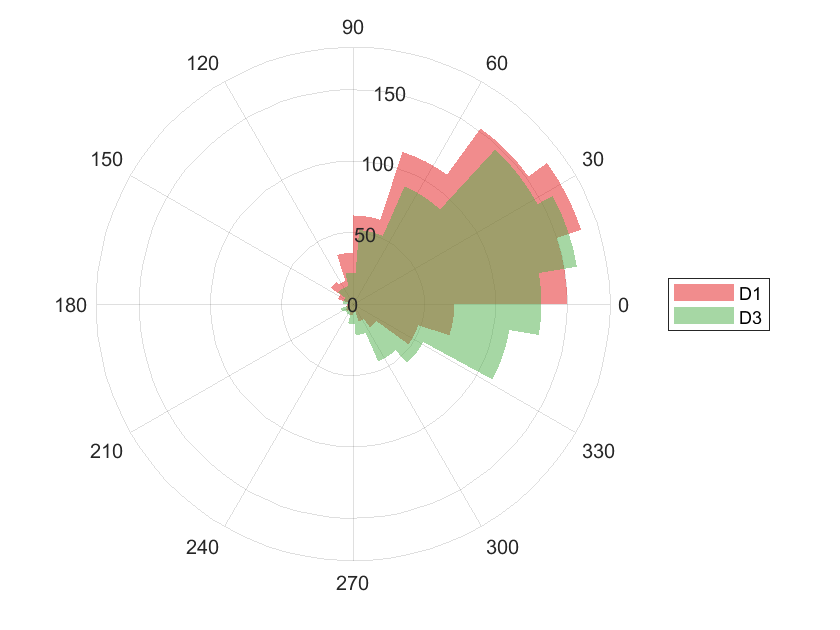

version = [];
showlaplace     = true;
showhilbert     = false;
if showlaplace == true
    version = [version '_laplace'];
end
if showhilbert == true
    version = [version '_hilbert'];
end

chanpair = {'Oz','PO3'};

% Colormap
map = brewermap(4,'Set1');

for subs = 1:length(subjects)
    director = [filepath filesep subjects{subs} filesep subjects{subs} version];
    
    if ~exist('stimlocked','var')
        stimlocked  = load([director '_lock1_phase.mat'],'dhist','dav','cellperms');  % dhists are chan*chan*timeperiod_of_interest*trial matrices
    end
    if ~exist('d3locked','var')
        d3locked    = load([director '_lock2_phase.mat'],'dhist','dav','cellperms');
    end
    
    d1hist = stimlocked.dhist(ismember(stimlocked.cellperms{1},chanpair{1}),ismember(stimlocked.cellperms{2},chanpair{2}),1,:);
    d3hist = d3locked.dhist(ismember(d3locked.cellperms{1},chanpair{1}),ismember(d3locked.cellperms{2},chanpair{2}),1,:);
    
    polars(subs) = figure;
    f1 = polarhistogram(d1hist,'facecolor',map(1,:),'facealpha',.5,'edgecolor','none');
    hold on;
    f3 = polarhistogram(d3hist,'facecolor',map(3,:),'facealpha',.5,'edgecolor','none');
    hold on;
    legend([f1 f3],{'D1','D3'});
    polars(subs).Visible = 'on';
end

#### Rotating data for cross-subject normalization

#### Paired t-test  across subjects on mean phase difference angles